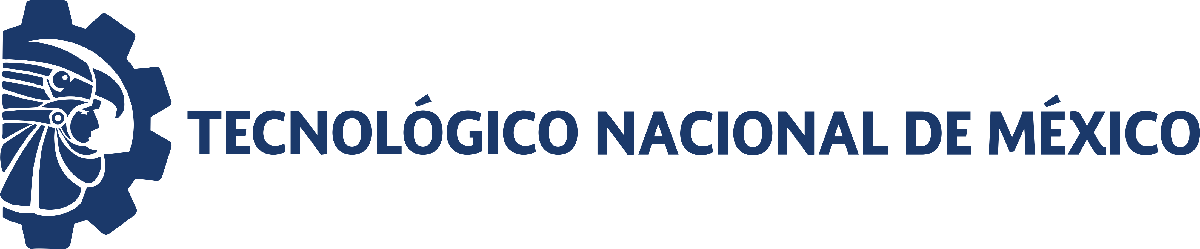                                 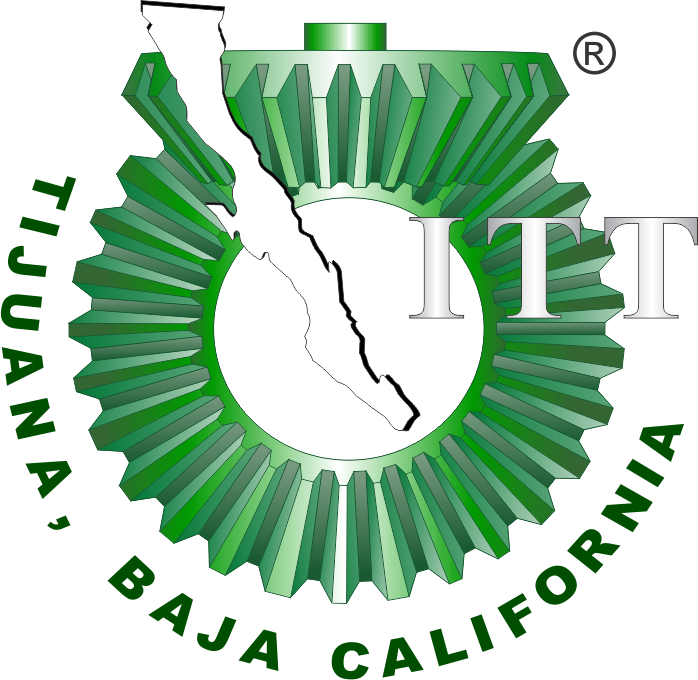

# Práctica dos: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

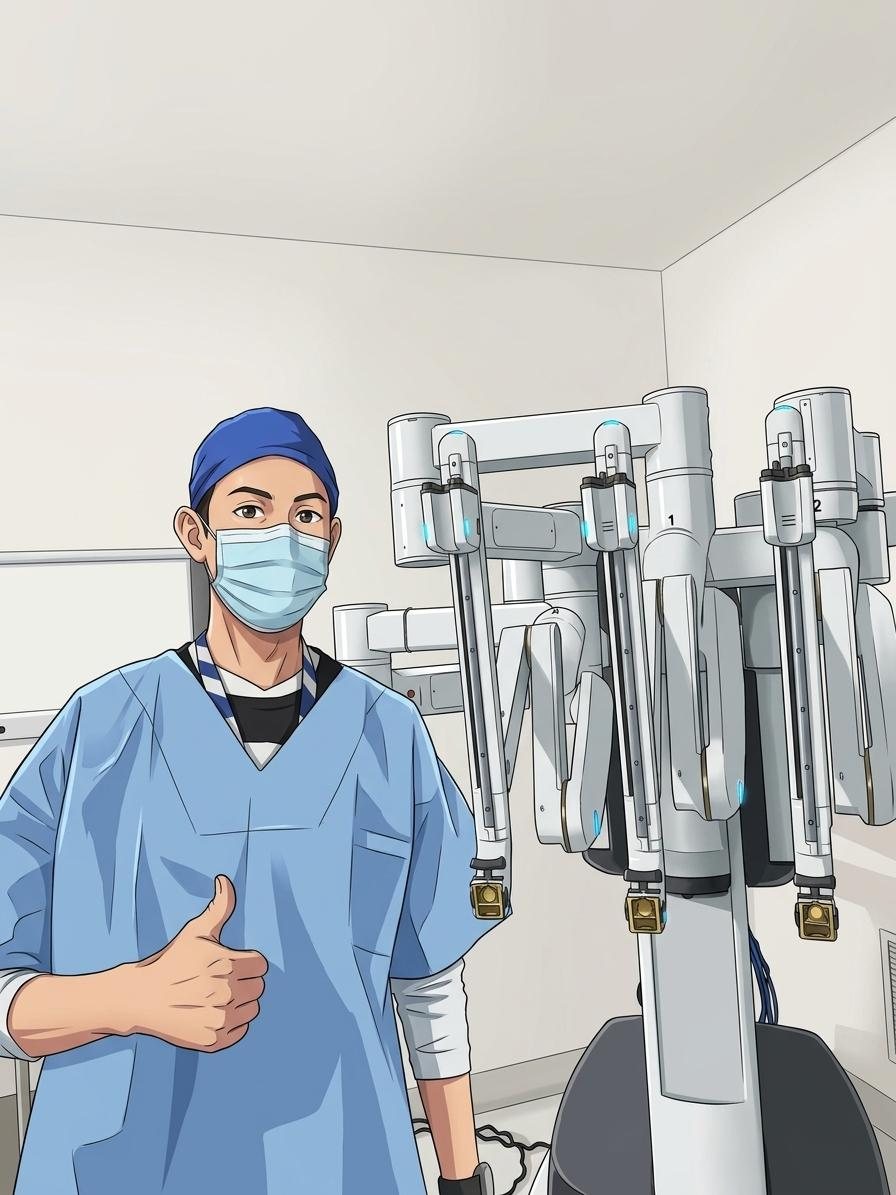

Nombre del alumno: Ernesto Jáuregui Bogarin

Número de control: 23212203

Correo institucional: l23212203**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema_Practica2')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
%set_param('Sistema_Practica1/Vs(t): CE/Vs','VectorFormat','1-D array');
x = sim('Sistema_Practica2',parameters);

t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');
writematrix(Pa,'signal.xlsx');

## Respuesta Normotenso

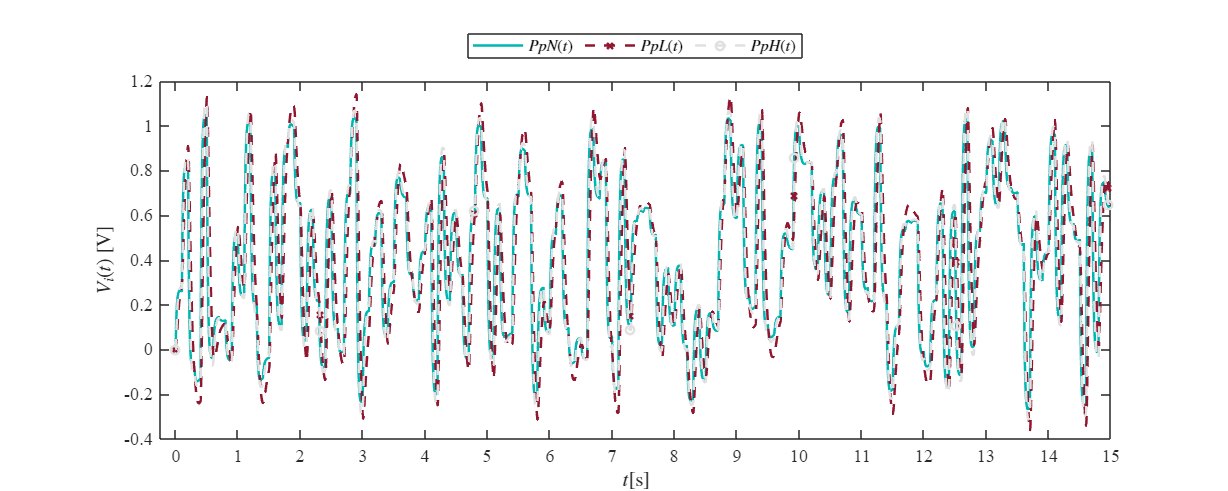

plotsignals(x.t, x.PpN, x.PpL, x.PpH,x.PIDL, x.PIDH, 'Normotenso');

## Respuesta Hipotenso

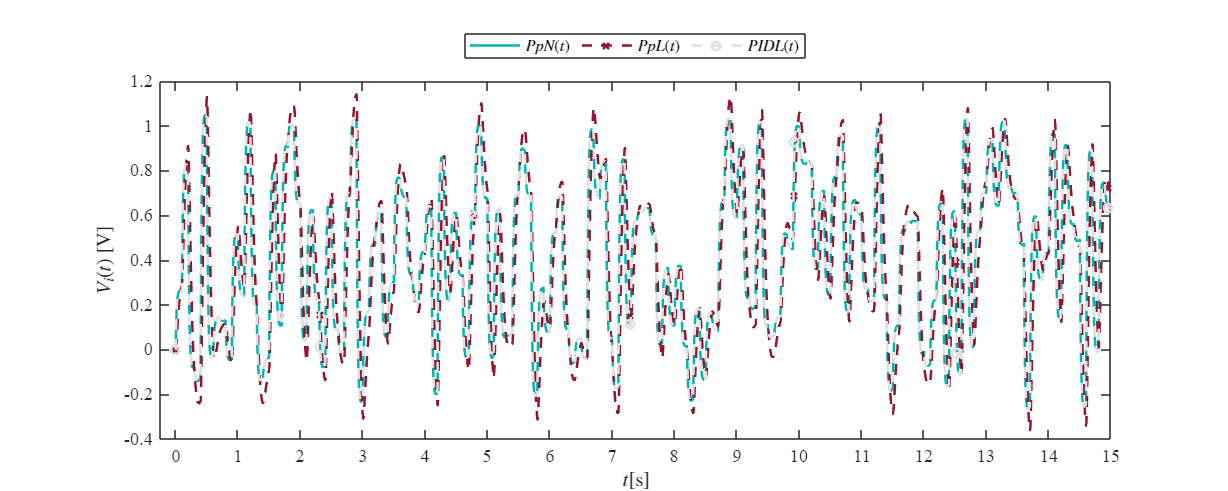

plotsignals(x.t, x.PpN, x.PpL, x.PpH,x.PIDL, x.PIDH, 'Hipotenso');

## Respuesta Hipertenso

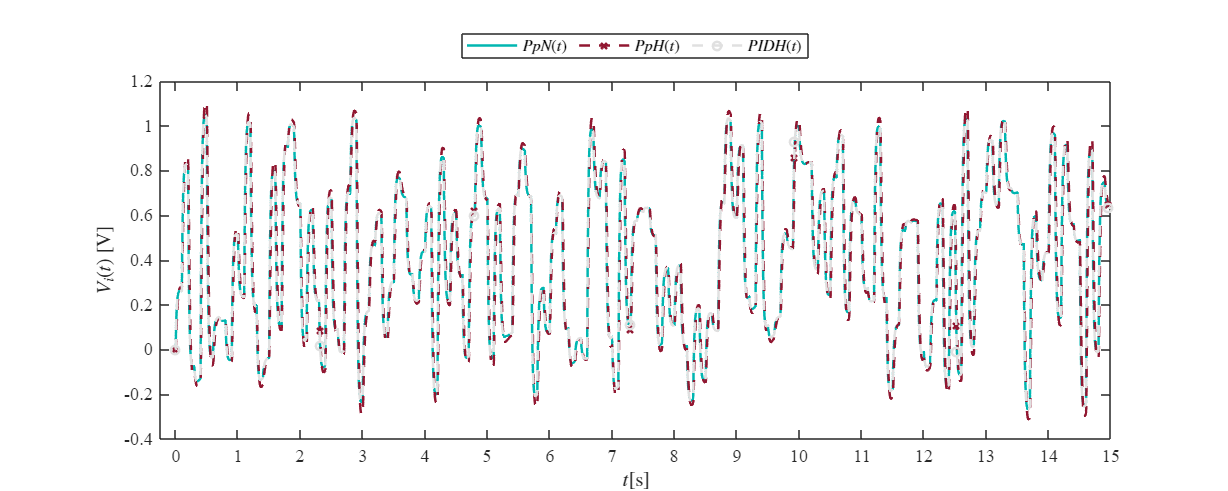

plotsignals(x.t, x.PpN, x.PpL, x.PpH,x.PIDL, x.PIDH, 'Hipertenso');

## Función: Respuestas de la simulación

function plotsignals(t, PpN, PpL, PpH, PIDL, PIDH, signal)

    set(figure(), 'color', 'w')
    set(gcf, 'units', 'inches', 'position', [1, 1, 25, 10])
    set(gca, 'fontname', 'times new roman', 'fontsize', 11)

    hold on;
    grid off;
    box on;

    clr1 = [0, 161, 156]/225;
    clr2 = [128, 20, 43]/225;
    clr3 = [198, 198, 198]/225;

    order = [clr1; clr2; clr3];
    colororder(order)

    if signal == "Normotenso"

        plot(t, PpN, '-', t, PpL, '--x', t, PpH, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, ...
            'MarkerIndices', 1:1e3:length(t));

        L = legend('$PpN(t)$', '$PpL(t)$', '$PpH(t)$');

    elseif signal == "Hipotenso"

        plot(t, PpN, '-', t, PpL, '--x', t, PIDL, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, ...
            'MarkerIndices', 1:1e3:length(t));

        L = legend('$PpN(t)$', '$PpL(t)$', '$PIDL(t)$');

    elseif signal == "Hipertenso"

        plot(t, PpN, '-', t, PpH, '--x', t, PIDH, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, ...
            'MarkerIndices', 1:1e3:length(t));

        L = legend('$PpN(t)$', '$PpH(t)$', '$PIDH(t)$');

    end

    set(L, 'interpreter', 'latex', ...
        'location', 'northoutside', ...
        'orientation', 'horizontal')

    xlabel('$t$[s]', 'interpreter', 'latex')
    ylabel('$V_i(t)$ [V]', 'interpreter', 'latex')

    xlim([-0.25 15])
    xticks(0:1:15)

    exportgraphics(gcf, [signal, '_matlab.pdf'], ...
        'contenttype', 'vector')

end
